
im=imread('saturn.png');
%im = imread('saturn.tiff');
im = rgb2gray(im);
fprintf("original image");

original image

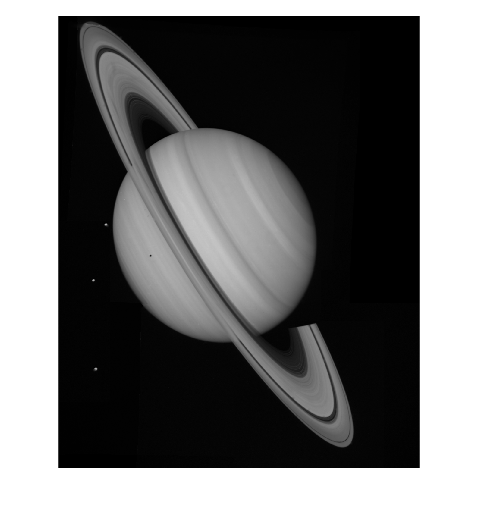

imshow(im);

im = im2double(im);

x=fft2(im);

%x= fftshift(x);

%{
x = abs(x);
x = fftshift(x);
x = log(1+abs(x));
imagesc(x);
%}
nn=1*1e+8;
%test to see 
nn = im2double(nn);
%nn=1*1e+10;
%fprintf("disp(x)");
%disp(x);

fprintf("x(10,10), x(10,11) x(11,10), x(11,11) numbers before");

x(10,10), x(10,11) x(11,10), x(11,11) numbers before

disp(x(9,9));

   1.1975e+03 + 1.4593e+03i



disp(x(10,10));

  -8.4509e+02 - 3.2341e+03i



disp(x(10,11));

  -2.8139e+02 - 3.7446e+02i



disp(x(11,10));

  -3.7792e+02 - 2.3433e+02i



disp(x(11,11));

   1.8969e+02 + 1.3887e+03i



%doing the change for 10,10,10,11 etc.
x(10,10)=x(10,10)+nn; x(10,11)=x(10,11)+nn;
x(11,10)=x(11,10)+nn; x(11,11)=x(11,11)+nn;
fprintf("x indexing");

x indexing

%disp(x([10:11,10:11]));
disp(x([10 11],[10 11]));

   1.0e+08 *

   1.0000 - 0.0000i   1.0000 - 0.0000i
   1.0000 - 0.0000i   1.0000 + 0.0000i





fprintf("x(10,10), x(10,11) x(11,10), x(11,11) numbers after");

x(10,10), x(10,11) x(11,10), x(11,11) numbers after

disp(x(9,9));

   1.1975e+03 + 1.4593e+03i



disp(x(10,10));

   9.9999e+07 - 3.2341e+03i



disp(x(10,11));

   1.0000e+08 - 3.7446e+02i



disp(x(11,10));

   1.0000e+08 - 2.3433e+02i



disp(x(11,11));

   1.0000e+08 + 1.3887e+03i



%increased to not just include (10 ,11) (10,11) row,columsn but include 9 and 12 to 
%get whole 4 by 4 matrix since medfilt2 uses 3x3 matrix by defauly
%z = x([9 10 11 12],[9 10 11 12]);

%getting z subimage
z = x(9:12,9:12);

%{
fprintf("z numbers")
disp(z(1,1));
disp(z(1,2));
disp(z(2,1));
disp(z(2,2));
%}
fprintf("z numbers")

z numbers

disp(z(2,2));

   9.9999e+07 - 3.2341e+03i



disp(z(2,3));

   1.0000e+08 - 3.7446e+02i



disp(z(3,2));

   1.0000e+08 - 2.3433e+02i



disp(z(3,3));

   1.0000e+08 + 1.3887e+03i




%checking if x and y are the same for 10,10 10,11 etc.
fprintf("disp(z) before medfilt");

disp(z) before medfilt

disp(z);

   1.0e+08 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   1.0000 - 0.0000i   1.0000 - 0.0000i  -0.0000 + 0.0000i
  -0.0000 - 0.0000i   1.0000 - 0.0000i   1.0000 + 0.0000i   0.0000 - 0.0000i
  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i



%do medfilt2 on z subimage
z =medfilt2(real(z));

%doing zeros gives original image 
%replace all fluctuations with zero 
%along with surrounding area 4x4
%z = zeros(4,4);


%x = medfilt2(real(x));
fprintf("disp(z) after medfilt");

disp(z) after medfilt

disp(z);

   1.0e+03 *

         0    0.5046    0.0468         0
    0.5046    1.1975    0.5046    0.0468
         0    0.8303    0.4620         0
         0         0    0.2881         0



%x = medfilt2((z));

%{
x(10,10) = z(1,1);
x(10,11) = z(1,2);
x(11,10) = z(2,1);
x(11,11) = z(2,2);
%} 
%need to probably replace whole 4x4 matrix with new z patch

%{
x(9,9) = z(1,1);
x(9,10) = z(1,2);
x(9,11) = z(1,3);
x(9,12) = z(1,4);
x(10,9) = z(2,1);

x(10,10) = z(2,2);
x(10,11) = z(2,3);

x(10,12) = z(2,4);

x(11,9) = z(3,1);

x(11,10) = z(3,2);
x(11,11) = z(3,3);

x(11,12) = z(3,4);

x(12,9) = z(4,1);
x(12,10) = z(4,2);
x(12,11) = z(4,3);
x(12,12) = z(4,4);
%}

%setting the 
%medfilter nums in z to x 
x(9:12,9:12) = z;
%x(10:11,10:11) = z(2:3,2:3);

fprintf("x(10,10), x(10,11) x(11,10), x(11,11) numbers after replace");

x(10,10), x(10,11) x(11,10), x(11,11) numbers after replace

disp(x(9,9));

     0



disp(x(10,9));

  504.6350



disp(x(10,10));

   1.1975e+03



disp(x(10,11));

  504.6350



disp(x(11,10));

  830.3229



disp(x(11,11));

  461.9601




y=real(ifft2(x));
y = im2uint8(y);
%y = ifft2(real(x));
disp(y);

  Columns 1 through 22

     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0   


%y = ifft2(x);
%y = real(y);
%z_real= real(ifft2(z));

fprintf("y");

y

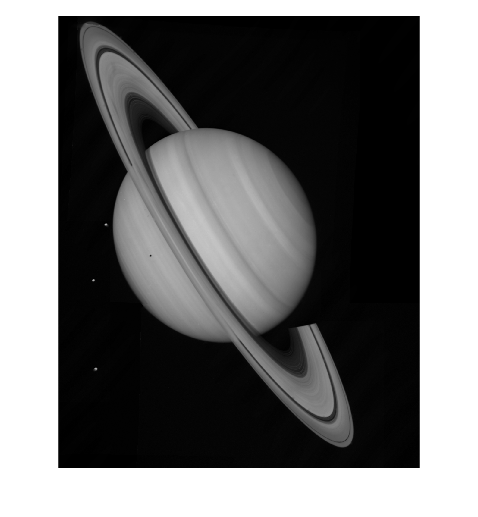

imshow(y);

imshow(abs(y));

%{
fprintf("z_real (should be fixed noise)");
imshow(z_real)
%}

%{
im=imread('saturn.png');
im = rgb2gray(im);
imshow(im);
x=fft2(im);
nn=1*1e+8;%8
x(10,10)=x(10,10)+nn; x(10,11)=x(10,11)+nn;
x(11,10)=x(11,10)+nn; x(11,11)=x(11,11)+nn;
y=real(ifft2(x));
imshow(y);
%}